clc;
close all;
clear variables;

Indirektni metod Ljapunova

digits(7);
[L, R, C, E, x2e] = nominalni_parametri();
[G, A, B, H, ue] = linearizacija()

G =
 
      2646.8 (s-606.3)
  -------------------------
  (s^2 + 40.92s + 1.618e04)
 
Continuous-time zero/pole/gain model.



A =          0   21.8621
 -740.0555  -40.9165


B = 	1.0e+03 *

    2.1684
    2.6468


H =      0     1


ue = 0.6522


syms s
    karakteristicni_polinom = vpa(simplifyFraction(det(s*eye(length(A)) - A)))

$$karakteristicni\_polinom = s^{2}+40.91653\,s+16179.17$$

    sol = solve(karakteristicni_polinom == 0, s, 'ReturnConditions',true);
    nule = sol.s

$$nule = \left(\begin{array}{c} -20.45826-125.5414\,\mathrm{i}\\ -20.45826+125.5414\,\mathrm{i} \end{array}\right)$$

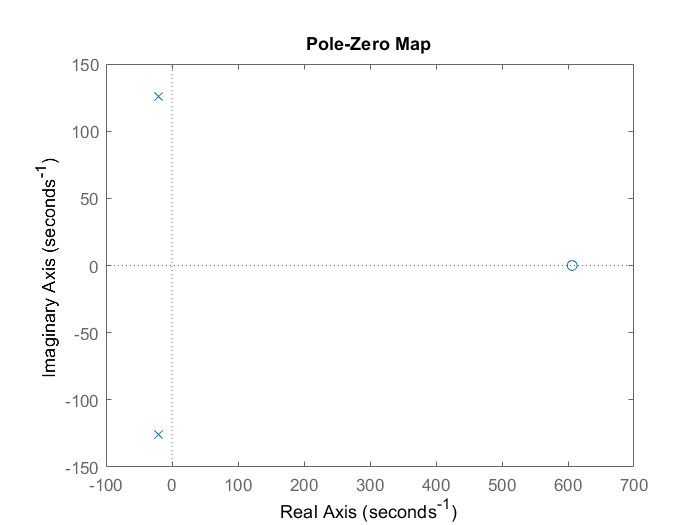

    pzmap(G)

sim_file_name = 'nelinearni_model_sim';
sim_duration = 5;
open_system(sim_file_name)
out=sim(sim_file_name);


### Plotovanje

#### Nelinearni model

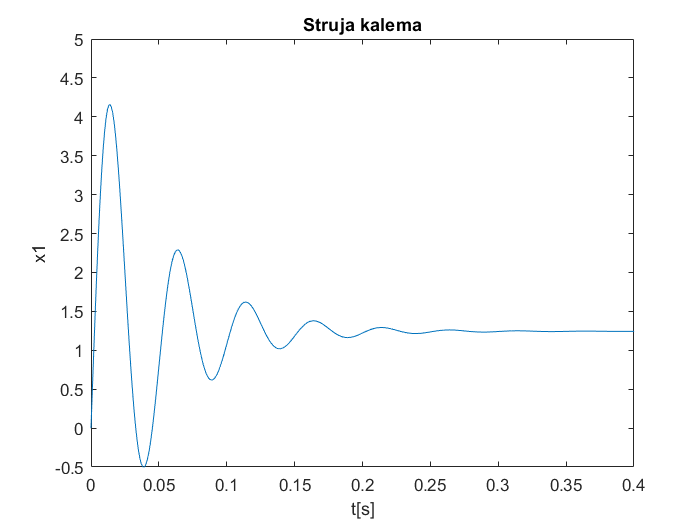

figure()
plot(out.x1);
title('Struja kalema');
xlim([0 0.4]); ylim([-0.5 5]);
ylabel('x1'); xlabel('t[s]');

rising_edge_info = stepinfo(out.x1.Data,out.tout)

rising_edge_info = struct with fields:
        RiseTime: 0.0021
    SettlingTime: 0.1953
     SettlingMin: -0.5025
     SettlingMax: 4.1587
       Overshoot: 234.3004
      Undershoot: 40.3958
            Peak: 4.1587
        PeakTime: 0.0140


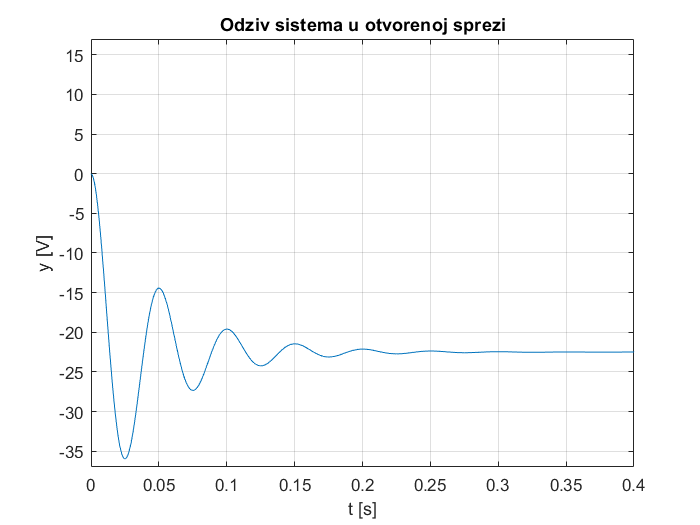


figure()
plot(out.x2);
title('Odziv sistema u otvorenoj sprezi')
xlim([0 0.4]); ylim([-37 17]);
ylabel("y [V]"); xlabel('t [s]');
grid on

rising_edge_info = stepinfo(out.x2.Data,out.tout)

rising_edge_info = struct with fields:
        RiseTime: 0.0092
    SettlingTime: 0.1814
     SettlingMin: -35.9812
     SettlingMax: -14.4227
       Overshoot: 59.9164
      Undershoot: 0
            Peak: 35.9812
        PeakTime: 0.0250


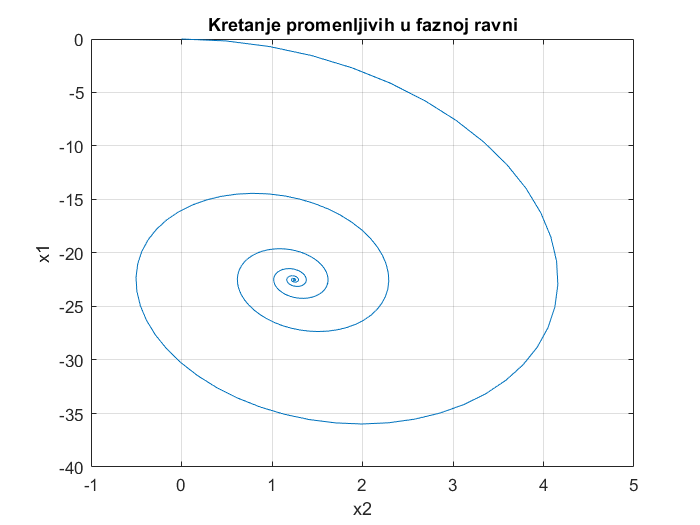





figure()
plot(out.x1.Data,out.x2.Data);
grid on;
title('Kretanje promenljivih u faznoj ravni');
ylabel('x1'); xlabel('x2');

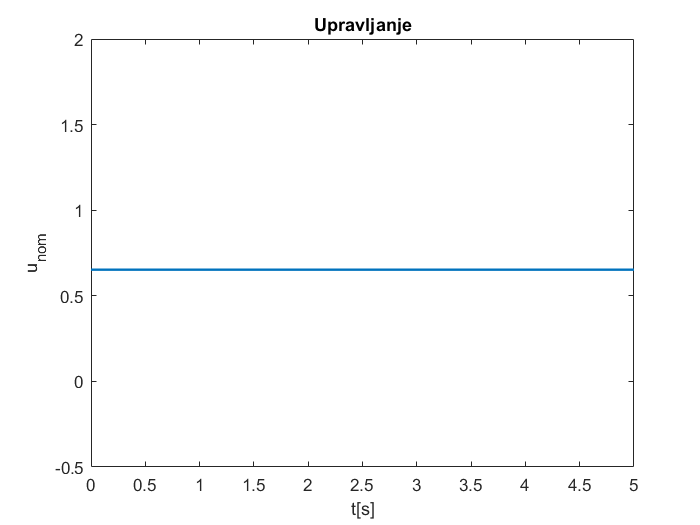


figure()
plot(out.tout,out.u*ones(length(out.x1.Time),1),'linewidth',1.4);
title('Upravljanje')
ylabel('u_{nom}'); xlabel('t[s]');

#### Nelinearni model sa sumom

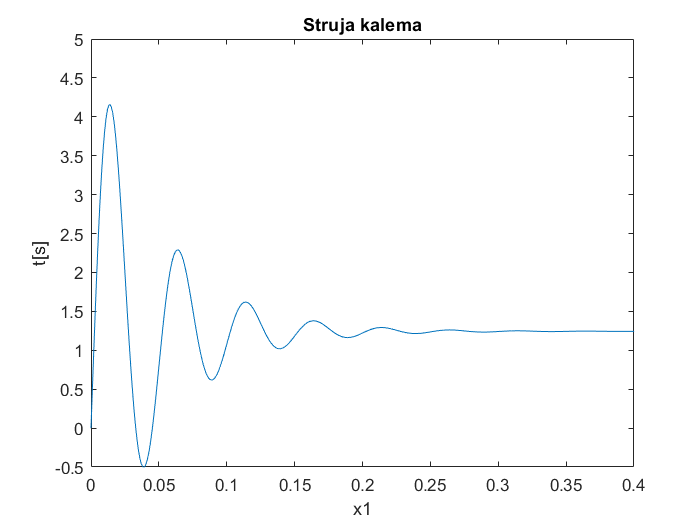

figure()
plot(out.x1_sum);
title('Struja kalema');
xlim([0 0.4]); ylim([-0.5 5]);
xlabel('x1'); ylabel('t[s]');

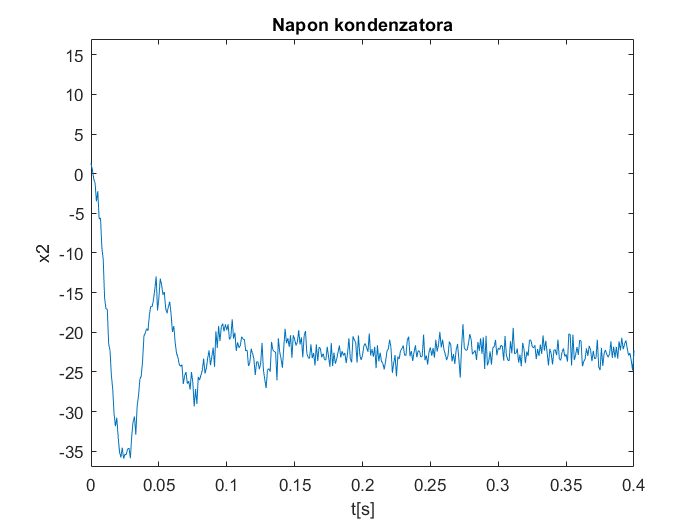


figure()
plot(out.x2_sum);
title('Napon kondenzatora')
xlim([0 0.4]); ylim([-37 17]);
ylabel('x2'); xlabel('t[s]');

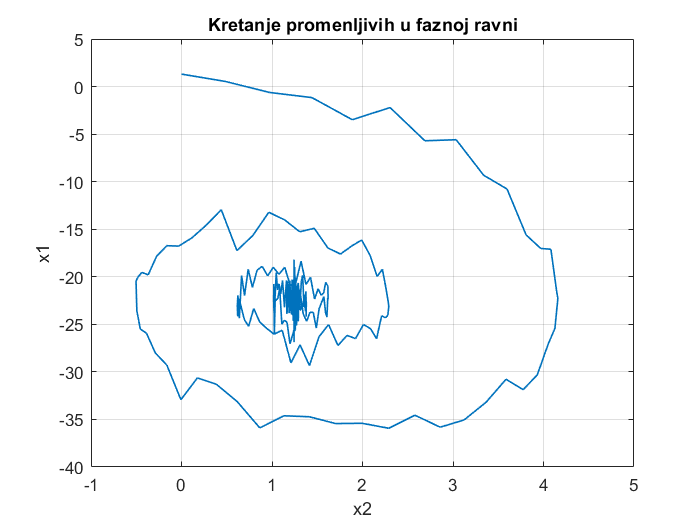




figure()
plot(out.x1_sum.Data,out.x2_sum.Data,'linewidth',1);
grid on;
title('Kretanje promenljivih u faznoj ravni');
ylabel('x1'); xlabel('x2');


figure()
plot(out.tout,out.u*ones(length(out.x1.Time),1),'linewidth',1.4);
title('Upravljanje')
ylabel('u_{nom}'); xlabel('t[s]');

### Testiranje robusnosti

C_nom = C;
C_vals = [0.8 , 0.9, 1.0, 1.1, 1.2];
C_name = cell(length(C_vals), 1);
for i = 1:length(C_vals)
    C_name{i} = num2str(C_vals(i)) + " C_{nom}";
end



Simulacija

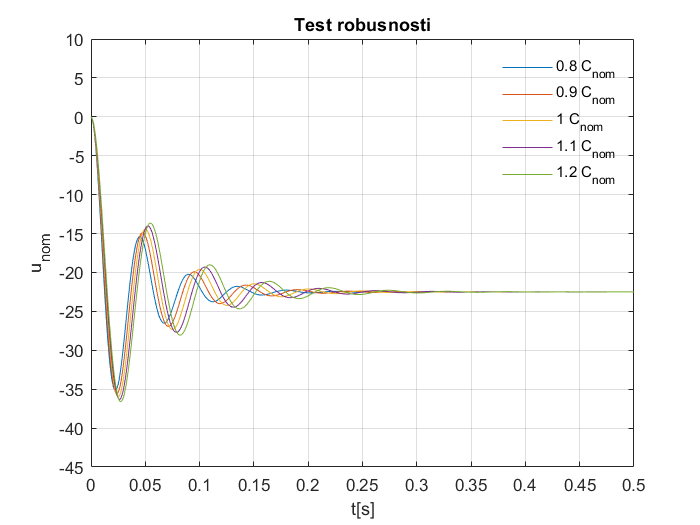

for i = 1:length(C_vals)    
    C = C_vals(i) * C_nom;
    out_rob(i) = sim(sim_file_name);
end
close all;

figure(1)

for i=1:length(C_vals)
    
    plot(out_rob(i).x2,'DisplayName', C_name{i}); 
    legend('Location', 'northeast',"Box","off")
    hold on;
end
title('Test robusnosti')
xlim([0 0.5]); ylim([-45 10]); grid on;
 ylabel('u_{nom}','Interpreter', 'tex'); xlabel('t[s]');